rawDataPath_full = '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000027/data.raw.h5';
rawDataPath_filt = '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000028/data.raw.h5';

rawData_full = mxw.fileManager(rawDataPath_full)

rawData_full =   fileManager with properties:

      referencePath: '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000027/data.raw.h5'
             wellID: 1
           isFolder: 0
             nFiles: 1
        nRecordings: 1
            version: '20190530'
       fileNameList: {'/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000027/data.raw.h5'}
            fileObj: [1×1 mxw.dataFunctions.fileInterface_2]
             rawMap: [1×1 struct]
       processedMap: [1×1 struct]
    extractedSpikes: [1×1 struct]
     bandPassFilter: [1×1 mxw.util.bandpass]


rawData_filt = mxw.fileManager(rawDataPath_filt)

rawData_filt =   fileManager with properties:

      referencePath: '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000028/data.raw.h5'
             wellID: 1
           isFolder: 0
             nFiles: 1
        nRecordings: 1
            version: '20190530'
       fileNameList: {'/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000028/data.raw.h5'}
            fileObj: [1×1 mxw.dataFunctions.fileInterface_2]
             rawMap: [1×1 struct]
       processedMap: [1×1 struct]
    extractedSpikes: [1×1 struct]
     bandPassFilter: [1×1 mxw.util.bandpass]


electrodes = rawData_full.rawMap(1).map.electrode(500:500);
electrodes = transpose(electrodes)

electrodes = int32
3470


[rawTraces,~,~] = rawData_full.extractBPFData(20000,(59*20000),'files',1,'electrodes',electrodes);

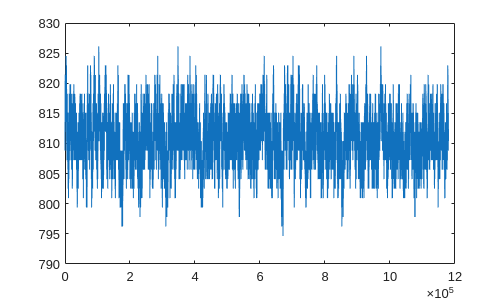

plot(rawTraces)

electrodes = rawData_filt.rawMap(1).map.electrode(500:500);
electrodes = transpose(electrodes)

electrodes = int32
3470


[rawTraces,~,~] = rawData_filt.extractBPFData(20000,(59*20000),'files',1,'electrodes',electrodes);

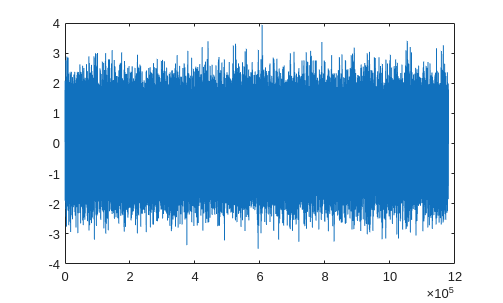

plot(rawTraces)

rawData_filt.bandPassFilter.lowcut

ans = 300